# Exercice 11 - Optimisation multi-objectifs 

## Données

Un dispatcher d'énergies dispose de 5  centrales thermiques de différentes technologiques qui produisent de l'électricité. Il est capable de prédire le coût de chaque centrale à partir d'une relation de type : 


$$C_I \left(P_I \right)=a_I {\left(P_I \right)}^2 +b_I {\left(P_I \right)} +c_I$$


$C_I$ est le coût de production selon la puissance produite ($P_I$) pour l'unité *I*. 

Chaque centrale a des limites de production : $P_{I,\min } {\le P}_I \le P_{I,\max }$

Chaque centrale produit des émissions polluantes. Le dispatcher dispose de relation pour estimer la quantité totale ($T_I$) de polluants produite en kg/j par chaque centrale en fonction de sa puissance thermique ($P_I$) :  


$$T_I \left(P_I \right)=d_I {\left(P_I \right)}^2 +e_I {\left(P_I \right)} +f_I$$


Les données des 5 centrales sont disponibles dans le fichier `data_Exercice11.mat` (`load data_Exercice11`): coefficients `A, B, C, D, E` et `F` des deux formules ci-dessus ainsi que `Pmin` et `Pmax`. 

Toutes les puissances sont exprimées en MW.

clear 

load data_Exercice11

## Partie 1

Vecteur initial

X0 = (Pmax/2) ; %Vecteur X initial

Données

P_demandee = [281 ; 350 ; 400 ; 500 ; 550 ; 650 ; 750 ; 850 ; 900 ; 998] ;  % Puissance demandée par le client 
n = length(X0) ; %La dimension de X 

% création des vecteurs pour le trcé du graphique 
Cout_opti = zeros(length(P_demandee),1) ;
Centrale_1 = zeros(length(P_demandee),1) ;
Centrale_2 = zeros(length(P_demandee),1) ;
Centrale_3 = zeros(length(P_demandee),1) ;
Centrale_4 = zeros(length(P_demandee),1) ;
Centrale_5 = zeros(length(P_demandee),1) ;

Fonction objectif 

fun_obj = @(X) (sum ([ A .* X.^2  + B .* X + C])); %focntion objectif qui calcule le cout global pour une puissance égale à la puissance demandée

Début de la boucle for

for i = 1 : length(P_demandee)

Contraintes linéaires

% Contraintes linéaires inégalités 

Aineq =  [] ; 

bineq = [] ; 
  
%Contraintes linéaires égalités :

Aeq = ones(1,n) ;

beq = P_demandee(i)  ; 

Bornes de définition du problème

lb = Pmin ; 

ub = Pmax ; 

%Les bornes du problème sont les puissances minimales et maximales qui sont
%admises par la centrale

Appel de la fonction fmincon

option=optimoptions('fmincon','display','iter');
[x, fval, flag, output] = fmincon(fun_obj,X0,Aineq,bineq,Aeq,beq,lb,ub,'',option);

Cout_opti(i) = sum(x) ; 

Centrale_1(i) = x(1) ; 
Centrale_2(i) = x(2) ; 
Centrale_3(i) = x(3) ; 
Centrale_4(i) = x(4) ; 
Centrale_5(i) = x(5) ; 

end 

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    2.180e+02    5.494e+02
    1      12    2.002054e+05    2.062e+02    3.439e+02    4.001e+01
    2      18    1.339785e+05    1.198e+02    3.479e+02    4.389e+01
    3      24    1.281883e+05    1.124e+02    3.418e+02    7.819e+00
    4      30    1.279441e+05    1.121e+02    1.409e+02    3.055e-01
    5      36    1.177464e+05    9.464e+01    1.517e+02    9.417e+00
    6      42    1.176866e+05    9.454e+01    1.518e+02    6.433e-02
    7      48    1.090356e+05    7.904e+01    1.452e+02    1.216e+01
    8      54    1.052703e+05    7.028e+01    1.812e+02    6.183e+00
    9      60    8.584304e+04    8.748e+00    5.172e+01    4.651e+01
   10      66    8.415774e+04    6.350e-01    1.145e+01    8.500e+00
   11      72    8.410961e+04    4.091e-01    8.492e+00    6.923e-01
   12      78    8.410911e+04    4.065e-01    2

Tracé des courbes 

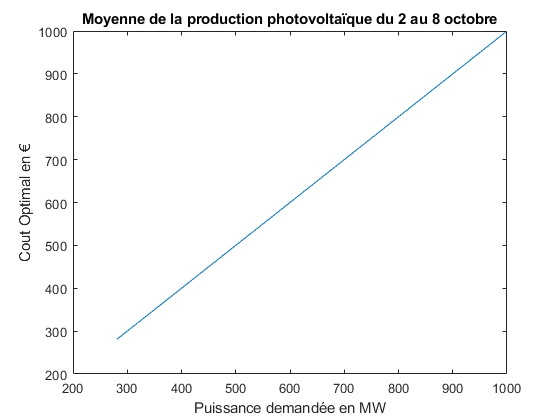

plot(P_demandee, Cout_opti)
title('Moyenne de la production photovoltaïque du 2 au 8 octobre'); 
xlabel('Puissance demandée en MW') ;
ylabel('Cout Optimal en €') ;

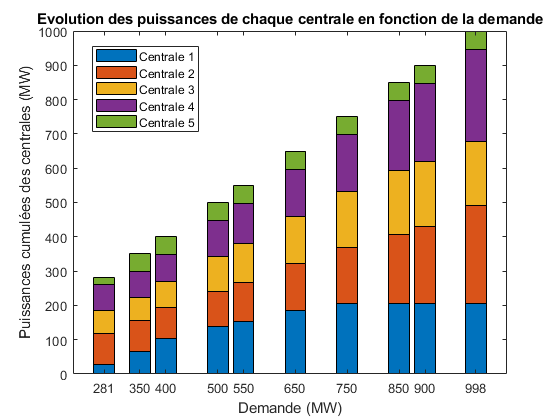


Tot_centrale = [Centrale_1 Centrale_2 Centrale_3 Centrale_4 Centrale_5];
bar(P_demandee,Tot_centrale,'stacked')
xlabel('Demande (MW)')
ylabel('Puissances cumulées des centrales (MW)')
title(sprintf('Evolution des puissances de chaque centrale en fonction de la demande'))
legend('Centrale 1','Centrale 2','Centrale 3','Centrale 4','Centrale 5','Location',"best")

## Partie 2

Vecteur initial

X0_2 = Pmax/2 ; 

Données nécessaires à la partie 2

 P_demandee_2 = 400 ; % La puissance demandée est de 400 MW

Fonction objectif à minimiser 

fun_obj_2 = @(X) (sum ([ D .* X.^2  + E .* X + F])); %focntion objectif qui calcule la quantité de polluants produits pour une puissance


Contraintes linéaires

% Contraintes linéaires inégalités 

Aineq =  [] ; 

bineq = [] ; 
  
%Contraintes linéaires égalités :

Aeq_2 = ones(1,n) ;

beq_2 = P_demandee_2  ; 


Bornes de définition du problème

lb = Pmin ; 

ub = Pmax ; 

%Les bornes du problème sont les puissances minimales et maximales qui sont
%admises par la centrale comme pour la partie 1

Appel de la fonction fmincon

option=optimoptions('fmincon','display','iter');
[x_2, fval_2, flag, output] = fmincon(fun_obj_2,X0_2,Aineq,bineq,Aeq_2,beq_2,lb,ub,'',option);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    1.629292e+05    9.900e+01    4.986e+02
    1      12    1.248989e+05    9.205e+01    2.508e+02    5.622e+01
    2      18    1.137353e+05    7.891e+01    2.560e+02    2.208e+01
    3      24    1.134723e+05    7.858e+01    1.790e+02    4.461e-01
    4      30    1.064929e+05    6.086e+01    1.059e+02    1.518e+01
    5      36    8.817700e+04    2.272e+00    1.542e+02    3.518e+01
    6      42    8.716977e+04    0.000e+00    3.155e+01    1.821e+01
    7      48    8.708954e+04    0.000e+00    2.070e+00    5.497e+00
    8      54    8.708943e+04    0.000e+00    3.972e-01    4.006e-01
    9      60    8.708940e+04    0.000e+00    1.193e-03    1.313e-01
   10      66    8.708940e+04    0.000e+00    1.783e-05    2.284e-05

Local minimum found that satisfies the cons

Comparaison pour la répartition des centrales avec le critère économique et écologique 

x_1 = [Centrale_1(3) ;Centrale_2(3); Centrale_3(3); Centrale_4(3); Centrale_5(3)] ; 

Tracé de la courbe

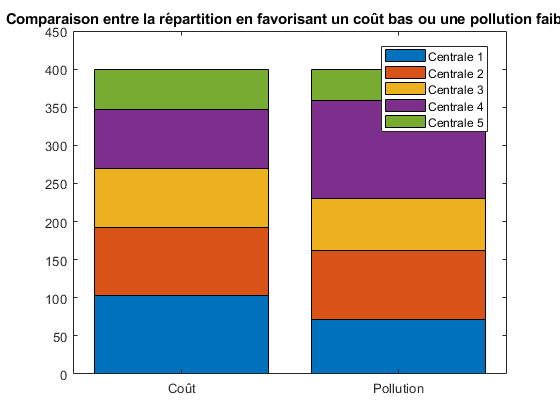

c = categorical([{'Coût'}, {'Pollution'}]);
bar(c, [x_1 x_2],'stacked')
legend('Centrale 1','Centrale 2','Centrale 3','Centrale 4','Centrale 5','Location',"best")
title('Comparaison entre la répartition en favorisant un coût bas ou une pollution faible');

## Partie 3

Définition des fonctions 

fun_1 = @(X) (sum ([ A .* X.^2  + B .* X + C]));
fun_2 = @(X) (sum ([ D .* X.^2  + E .* X + F]));

Données

P_demandee_3 = 400 ; % en MW

lb = Pmin ;% Définition des bornes 
ub = Pmax ;

x0 = Pmax/2 ; % initialistion

Aeq_3 = ones(1,n) ; % Contraintes linéaires égalités 
beq_3 = P_demandee_3  ;

Aineq_3 = [] ; 
bineq_3 = [] ; 


Méthode 1 : Pondération avec 11 valeurs entre 0 et 1 (sans les taxes et les pénalités financières)

ww = linspace(0,1,11); 
sol = zeros(length(x0),length(ww));
fsol = zeros(2,length(ww));

for i=1:length(ww)
    
    w = ww(i);
    fobj = @(x,w) w*fun_1(x) + (1-w)*fun_2(x);
    [x,f,flag,out]=fmincon(@(x) fobj(x,w),x0,[],[],Aeq_3,beq_3,lb,ub);
    sol(:,i)=x;
    fsol(:,i)=[fun_1(x) ; fun_2(x)] ;
    
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

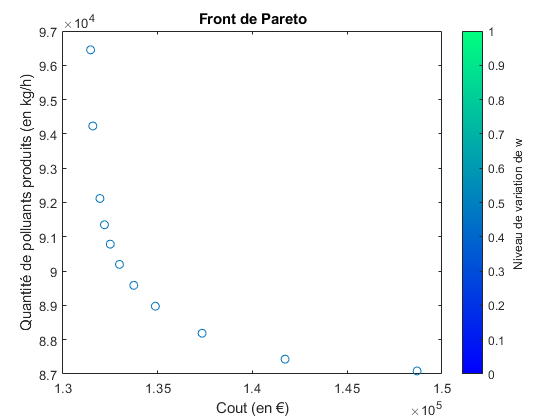

% Tracé Pareto
plot(fsol(1,:),fsol(2,:),'O')
colormap winter
c = colorbar;
c.Label.String = 'Niveau de variation de w ';
xlabel('Cout (en €)')
ylabel('Quantité de polluants produits (en kg/h)')
title('Front de Pareto')

Méthode 2 : Goal attainment Methode

goal_vect = linspace(350,450,11) ; 
weight_vect = linspace(0,1,11); 
sol_2 = zeros(length(x0),length(weight_vect));
fsol_2 = zeros(2,length(weight_vect));

for i=1:length(weight_vect)
    
    goal = goal_vect(i)
    weight = weight_vect(i);
    fobj = @(x,weight) weight * fun_1(x) + (1-weight) * fun_2(x);
    [x, fval, factor,flag,output] = fgoalattain(fobj,x0,goal,weight,Aineq_3,bineq_3,Aeq_3,beq_3,lb,ub,'',options) 
    sol_2(:,i)=x;
    fsol_2(:,i)=[fun_1(x) ; fun_2(x)] ;
    
end

goal = 350

Not enough input arguments.

Error in Exercice11_ThermalUnit (line 135)
    fobj = @(x,weight) weight * fun_1(x) + (1-weight) * fun_2(x);

Error in goalcon (line 63)
                f = feval(funfcn{3},x,varargin{:});

Error in <a href="matlab:matlab.internal.language.introspective.errorDocCallback('fgoalattain', 'C:\Program Files\MATLAB\R2021a\toolbox\optim\optim\fgoalattain.m', 437)" style="fon

## Conclusions

A partir de l'ensemble des résultats obtenus, quelles sont vos conclusions générales sur l'optimum de fonctionnement ?  

J'ai pu observer grâce aux trois différentes parties que les résultats d'optimisation différaient en fonction du poids des critères. En effet, nous avons comparé dans la partie deux, le cas où nous optimisons le coût et le cas où il s'agissait de l'impact environnemental. 

Dans la partie 1, nous pouvons conclure que le coût de la puissance demandée varie de manière linéaire.

Malgré le manque d'intégration des taxes pour la partie 3, nous pouvons tout de même comparé les deux critères grâce à un front de Pareto, qui nous permet de choisir une solution qui satisfait l'optimisation multicritère.

L'optimisation nécessite de comparer un maximum de critères afin de choisir une solution qui s'attisfaira un maximun de parties prenantes.

## Annexe : aides pour les graphiques

Ci dessous des codes qui peut vous inspirer pour le tracé de graphiqes. Remerciements à Mathieu Milhé.

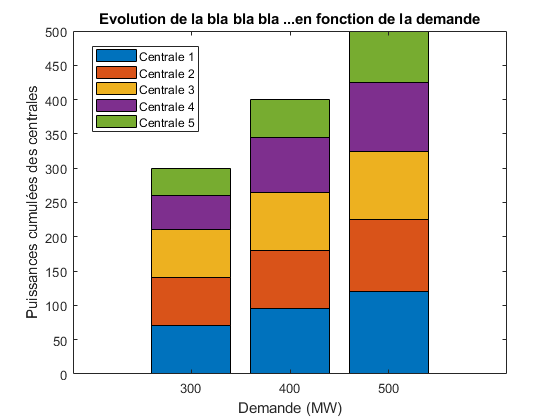

% exemple 1 (valeurs numériques aléatoires choisies)
Demande = 300:100:500;
P=[70 95 120
   70 85 105
   70 85 100
   50 80 100
   40 55 75];

figure
bar(Demande,P,'stacked')
xlabel('Demande (MW)')
ylabel('Puissances cumulées des centrales')
title(sprintf(['Evolution de la bla bla bla ...en fonction de la demande']))
legend('Centrale 1','Centrale 2','Centrale 3','Centrale 4','Centrale 5','Location',"best")

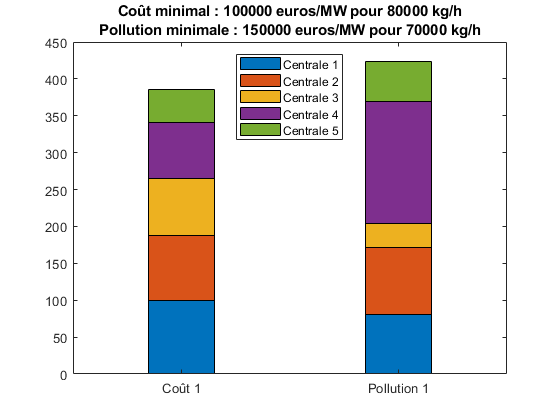

% exemple 2 (valeurs numériques aléatoires choisies)
x = categorical([{'Coût 1'}, {'Pollution 1'}]);
P = [100 88 77 76 45];
Q = [81 90 33 165 54];
C1=1e5; Pol1=8e4; C2=1.5e5; Pol2=7e4;
bar(x,[P;Q],0.3,'stacked')
legend('Centrale 1','Centrale 2','Centrale 3','Centrale 4','Centrale 5','Location',"best")
title(sprintf('Coût minimal : %3.0f euros/MW pour %4.0f kg/h\nPollution minimale : %3.0f euros/MW pour %4.0f kg/h',...
    C1,Pol1,C2,Pol2))

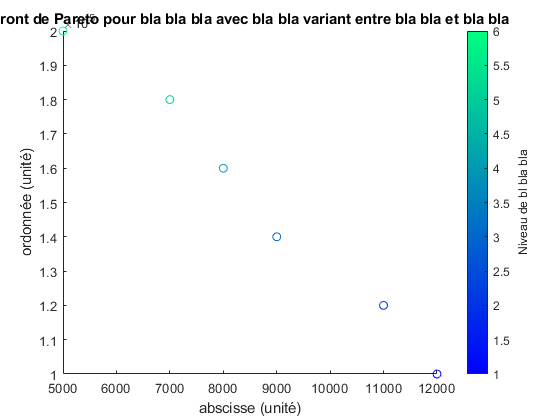

% exemple 3 (valeurs numériques aléatoires choisies)
X=1e5:0.2e5:2e5;
Y=[12 11 9 8 7 5].*1e3;
Z=1:6;
scatter(Y,X,[],Z)
colormap winter
c = colorbar;
c.Label.String = 'Niveau de bl bla bla';
xlabel('abscisse (unité)')
ylabel('ordonnée (unité)')
title('Front de Pareto pour bla bla bla avec bla bla variant entre bla bla et bla bla')